clear;
clc;
I = imread("pictures\rgb.jpg");
Q = 2;
REAL_SIM = false;
NOISE_TYPE = 0;
key = round(rand(1, 10000000));

if REAL_SIM
    N = 16;
    K = 11;
    funENCO = @HammingENCO;
    funDECO = @HammingDECO;
    ADD_NOISE = false;
else
    N = 7;
    K = 4;
    funENCO = @HMENCO;
    funDECO = @HMDECO;
    ADD_NOISE = true;
end

[code1, code2, code3] = jpegENCO(I, Q);

[code1, code2, code3] = BitsXor(code1, code2, code3, key);

[row, col, ~] = size(I);
disp((length(code1) + length(code2) + length(code3)) / (row * col * 3 * 8));

    0.1553



r1 = HammingSeq(code1, N, K, funENCO);
r2 = HammingSeq(code2, N, K, funENCO);
r3 = HammingSeq(code3, N, K, funENCO);

p1 = BlockDiv(r1, length(r1) / N);
p2 = BlockDiv(r2, length(r2) / N);
p3 = BlockDiv(r3, length(r3) / N);

if ADD_NOISE
    if NOISE_TYPE == 0
        noise_length = 350000;
        start = round(1000 * rand(1) + 1);
        noise = round(rand(1, noise_length));
        temp = p1(start: start + noise_length - 1);
        temp = double(temp - 48);
        temp = xor(temp, noise);
        p1(start: start + noise_length - 1) = char(temp + 48);
    elseif NOISE_TYPE == 1
        p1 = AWGNChannel(p1, 5);
        p2 = AWGNChannel(p2, 5);
        p3 = AWGNChannel(p3, 5);
    end
end

r1 = BlockDiv(p1, N);
r2 = BlockDiv(p2, N);
r3 = BlockDiv(p3, N);

code1 = InvHammingSeq(r1, N, K, funDECO);
code2 = InvHammingSeq(r2, N, K, funDECO);
code3 = InvHammingSeq(r3, N, K, funDECO);

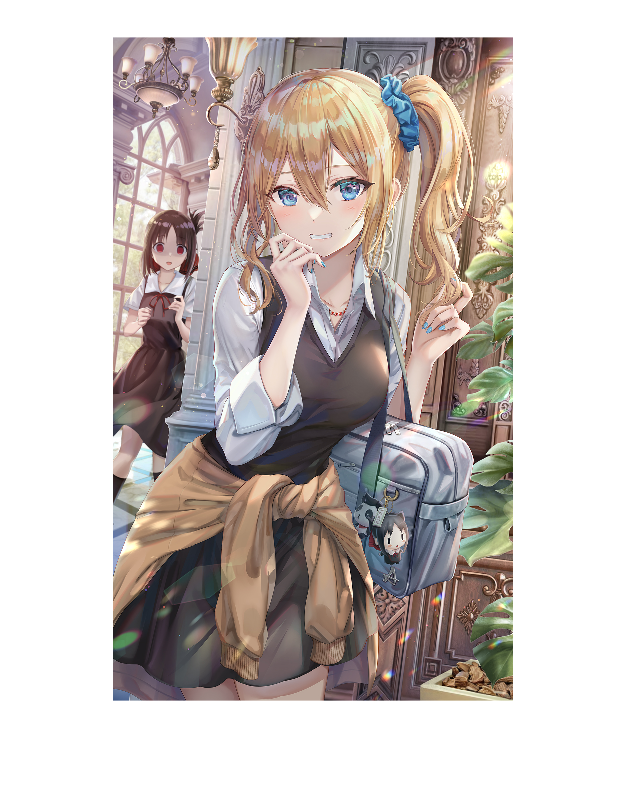

[code1, code2, code3] = BitsXor(code1, code2, code3, key);

out = uint8(jpegDECO(code1, code2, code3, Q));

figure;
imshow(I);

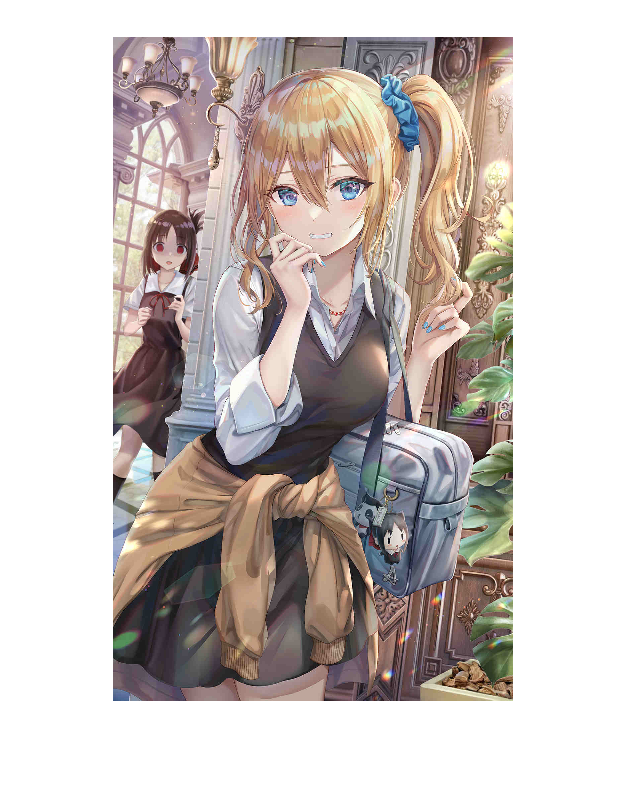

figure;
imshow(out);

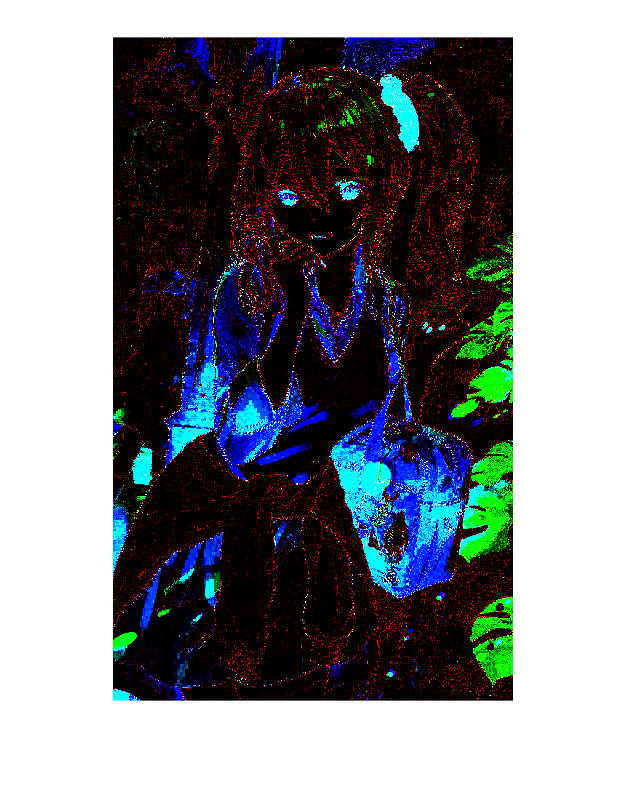

figure;
imshow((I - out(1: row, 1: col)) .^ 2);